clc; clear all; close all;
syms s C1 C2 C3 G ;

%Transfer function of the plant G
num = [7.4,14,6.7];
den = [1,2.6,10,17,8];
G = tf(num,den)

G =
 
        7.4 s^2 + 14 s + 6.7
  ---------------------------------
  s^4 + 2.6 s^3 + 10 s^2 + 17 s + 8
 
Continuous-time transfer function.
Model Properties



%Transfer function of the plant G
num = [0.57,4.1];
den = [0.23,1];
C1 = tf(num,den)

C1 =
 
  0.57 s + 4.1
  ------------
   0.23 s + 1
 
Continuous-time transfer function.
Model Properties



num = [0.57,2.4];
den = [0.13,1];
C2 = tf(num,den)

C2 =
 
  0.57 s + 2.4
  ------------
   0.13 s + 1
 
Continuous-time transfer function.
Model Properties



num = [0.57,1.6];
den = [0.091,1];
C3 = tf(num,den)

C3 =
 
  0.57 s + 1.6
  ------------
  0.091 s + 1
 
Continuous-time transfer function.
Model Properties


## Question a)

Plot, in one figure, the Nyquist contours for the three open-loop systems Li(s)—with i = 1,2,3. Utilize the nyquist function in Matlab for this purpose, consider the interval [−2,0.2] for the x-axis, the interval [−1,1] for the y-axis and include a legend. 

%Defines the open loop system
L1 = C1 *G

L1 =
 
          4.218 s^3 + 38.32 s^2 + 61.22 s + 27.47
  --------------------------------------------------------
  0.23 s^5 + 1.598 s^4 + 4.9 s^3 + 13.91 s^2 + 18.84 s + 8
 
Continuous-time transfer function.
Model Properties


L2 = C2 *G

L2 =
 
          4.218 s^3 + 25.74 s^2 + 37.42 s + 16.08
  --------------------------------------------------------
  0.13 s^5 + 1.338 s^4 + 3.9 s^3 + 12.21 s^2 + 18.04 s + 8
 
Continuous-time transfer function.
Model Properties


L3 = C3 *G

L3 =
 
           4.218 s^3 + 19.82 s^2 + 26.22 s + 10.72
  ----------------------------------------------------------
  0.091 s^5 + 1.237 s^4 + 3.51 s^3 + 11.55 s^2 + 17.73 s + 8
 
Continuous-time transfer function.
Model Properties


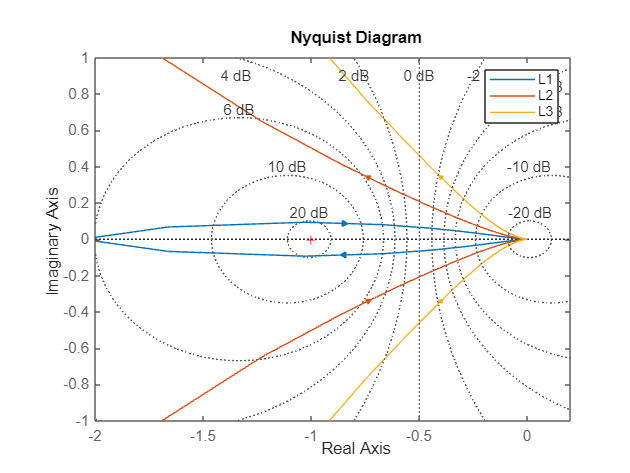


%Plots the plots
figure;
nyquist(L1,L2,L3)
xlim([-2, 0.2]);
ylim([-1, 1]);
legend;
grid on;

## Question b)

Use the Nyquist contours from question a) to determine, for each controller, whether the closed-loop interconnection in Figure 7 is stable. Please explain briefly how you came to this conclusion.

## Question c)

For each open-loop system Li(s)—with i = 1,2,3—determine the crossover frequency ωc in rad s , the phase margin PM in degrees, the gain margin GM in dB and the modulus margin MM in dB. You may round off your answer to one decimal place. If there are multiple frequencies satisfying |L(jω)| = 1 or ∠L(jω) = −180◦—that is, if there are multiple frequencies at which these margins could be calculated—please consider the one that is most critical in terms of stability. Note that: the margin command in Matlab will also consider this most critical frequency when calculating the PM and GM.

% Initialize results storage
systems = {'L1', 'L2', 'L3'};
open_loops = {L1, L2, L3};

% Print header
fprintf('System    wc (rad/s)    PM (°)    GM (dB)    MM (dB)\n');

System    wc (rad/s)    PM (°)    GM (dB)    MM (dB)


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------



% Loop through each system and calculate margins
for i = 1:length(systems)
    try
        % Check for system stability
        poles = pole(open_loops{i});
        if any(real(poles) >= 0)
            error('System is unstable (poles in the right half-plane).');
        end
        
        % Calculate gain margin (GM), phase margin (PM), and crossover frequencies
        [GM, PM, Wcg, Wcp] = margin(open_loops{i});

        % Calculate Modulus Margin (MM)
        [mag, phase, w] = bode(open_loops{i});
        mag = squeeze(mag); % Convert from 3D to 2D array
        MM_vals = abs(1 + squeeze(freqresp(open_loops{i}, w))); 
        MM = -20*log10(min(MM_vals)); 

        % Handle undefined margins
        if isempty(GM) || isempty(PM) || isempty(Wcp)
            GM_dB = NaN;
            PM_deg = NaN;
            Wcp_rad = NaN;
        else
            GM_dB = 20 * log10(GM); % Convert GM to dB
            PM_deg = PM; % Phase margin in degrees
            Wcp_rad = Wcp; % Crossover frequency in rad/s
        end

        % Print results
        fprintf('%-8s %10.1f %10.1f %10.1f %10.1f\n', systems{i}, Wcp_rad, PM_deg, GM_dB, MM);

    catch ME
        % Handle unstable or problematic systems
        fprintf('%-8s     UNSTABLE SYSTEM\n', systems{i});
        warning('Error analyzing system %s: %s', systems{i}, ME.message);
    end
end

L1              5.6       -5.3       -6.9       20.1
L2              5.6       25.9        Inf        7.2
L3              5.6       45.3        Inf        3.3


## Question d)

Determine the step response of the closed-loop system for each controllerCi(s) with i = 1,2,3. Add all plots on the same figure and plot over a duration of 7.6 seconds.

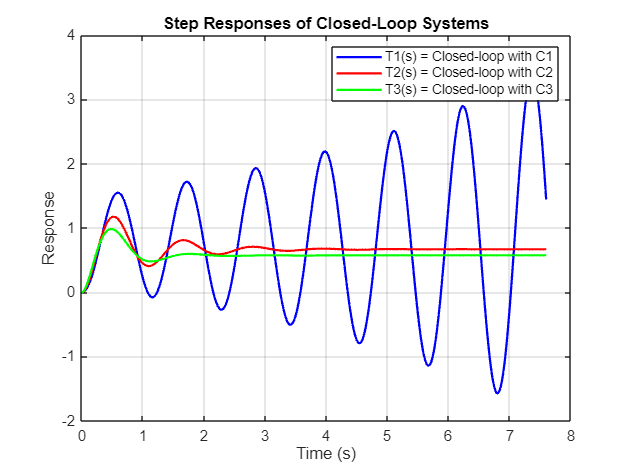

% Define closed‐loop systems for each controller
T1 = feedback(C1 * G, 1);  % Closed‐loop system with C1
T2 = feedback(C2 * G, 1);  % Closed‐loop system with C2
T3 = feedback(C3 * G, 1);  % Closed‐loop system with C3

% Time vector for simulation
t = 0:0.01:7.6;

% Compute step responses for each closed‐loop system
[y1, t1] = step(T1, t);  % Response for T1
[y2, t2] = step(T2, t);  % Response for T2
[y3, t3] = step(T3, t);  % Response for T3

% Plot step responses
figure;
plot(t1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(t2, y2, 'r', 'LineWidth', 1.5);
plot(t3, y3, 'g', 'LineWidth', 1.5);
grid on;
legend('T1(s) = Closed-loop with C1', 'T2(s) = Closed-loop with C2', 'T3(s) = Closed-loop with C3');
title('Step Responses of Closed-Loop Systems');
xlabel('Time (s)');
ylabel('Response');
hold off;

## Question e)

For the closed-loop response of each controller in question d, describe how well it is able to track the step reference signal. Compare each controller with respect to the following criteria: overshoot, steady state error, and settling time? Please explain, per criterium, which controller you would choose.



% Analyze step response characteristics using stepinfo
info1 = stepinfo(T1);

info2 = stepinfo(T2);
info3 = stepinfo(T3);

% Compute steady-state error (final value error from 1)
final_value1 = y1(end);
final_value2 = y2(end);
final_value3 = y3(end);
steady_state_error1 = abs(1 - final_value1);
steady_state_error2 = abs(1 - final_value2);
steady_state_error3 = abs(1 - final_value3);

% Display computed performance metrics
fprintf('Controller Comparison:\n');

Controller Comparison:


fprintf('Criterion                T1 (C1)    T2 (C2)    T3 (C3)\n');

Criterion                T1 (C1)    T2 (C2)    T3 (C3)


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------


fprintf('Overshoot (%%)          %8.2f   %8.2f   %8.2f\n', info1.Overshoot, info2.Overshoot, info3.Overshoot);

Overshoot (%)               NaN      75.91      71.58


fprintf('Settling Time (s)       %8.2f   %8.2f   %8.2f\n', info1.SettlingTime, info2.SettlingTime, info3.SettlingTime);

Settling Time (s)            NaN       3.55       1.98


fprintf('Steady-State Error      %8.4f   %8.4f   %8.4f\n', steady_state_error1, steady_state_error2, steady_state_error3);

Steady-State Error        0.4442     0.3322     0.4274



% Determine best controller based on each criterion
overshoots = [info1.Overshoot, info2.Overshoot, info3.Overshoot];
settling_times = [info1.SettlingTime, info2.SettlingTime, info3.SettlingTime];
ss_errors = [steady_state_error1, steady_state_error2, steady_state_error3];

[~, best_over_idx] = min(overshoots);
[~, best_settle_idx] = min(settling_times);
[~, best_ss_idx] = min(ss_errors);

controllers = {'C1', 'C2', 'C3'};
fprintf('\nBest controller based on overshoot: %s\n', controllers{best_over_idx});


Best controller based on overshoot: C3


fprintf('Best controller based on settling time: %s\n', controllers{best_settle_idx});

Best controller based on settling time: C3


fprintf('Best controller based on steady-state error: %s\n', controllers{best_ss_idx});

Best controller based on steady-state error: C2



% Additional descriptive analysis:
fprintf('\nDescriptive Analysis:\n');


Descriptive Analysis:


fprintf('For overshoot, %s exhibits the smallest overshoot, indicating it overshoots the desired value the least.\n', controllers{best_over_idx});

For overshoot, C3 exhibits the smallest overshoot, indicating it overshoots the desired value the least.


fprintf('For settling time, %s settles to the steady-state value the fastest.\n', controllers{best_settle_idx});

For settling time, C3 settles to the steady-state value the fastest.


fprintf('For steady-state error, %s tracks the reference most accurately, achieving the smallest error.\n', controllers{best_ss_idx});

For steady-state error, C2 tracks the reference most accurately, achieving the smallest error.


fprintf('Depending on which performance criterion is most critical for your application, you may choose the corresponding controller accordingly.\n');

Depending on which performance criterion is most critical for your application, you may choose the corresponding controller accordingly.


## Question f)

After some experimentation, your RWP suffers a bit of damage to the damper dφ , resulting in a 90% decrease in the damping coefficient. From a practical perspective, it is therefore important that closed-loop performance is not significantly affected by such small changes. Adjust, for this question only, the system parameters to the values stated above, and repeat the simulations in question d. Add the resulting plot to the answerform_5.docx document. The change in damping results in a new general equation of the transfer function

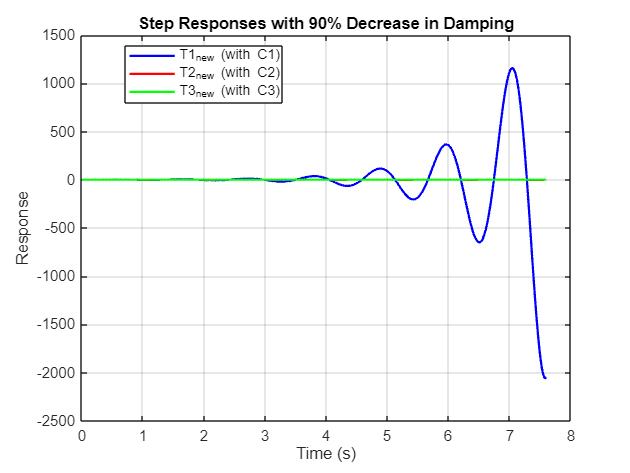

% Define the new G(s) with decreased damping
num_new = [7.4, 14, 6.7]; 
den_new = [1, 0.43, 10, 15, 8];  % Updated denominator reflecting the 90% damping reduction
G_new = tf(num_new, den_new);

% Assume controllers C1, C2, C3 are already defined from previous sections.

% Compute new closed-loop systems with the damaged plant
T1_new = feedback(C1 * G_new, 1);
T2_new = feedback(C2 * G_new, 1);
T3_new = feedback(C3 * G_new, 1);

% Define a time vector over 7.6 seconds for simulation
time = 0:0.01:7.6;  % Fine resolution time vector

% Compute step responses for each closed-loop system
[y1_new, t1_new] = step(T1_new, time);
[y2_new, t2_new] = step(T2_new, time);
[y3_new, t3_new] = step(T3_new, time);

% Plot step responses for the new closed-loop systems
figure;
plot(t1_new, y1_new, 'b', 'LineWidth', 1.5); 
hold on;
plot(t2_new, y2_new, 'r', 'LineWidth', 1.5);

plot(t3_new, y3_new, 'g', 'LineWidth', 1.5);
grid on;
legend('T1_{new} (with C1)', 'T2_{new} (with C2)', 'T3_{new} (with C3)', 'Location', 'best');
title('Step Responses with 90% Decrease in Damping');
xlabel('Time (s)');
ylabel('Response');
hold off;

## Question g)

Describe how the closed-loop response of each controller is affected by these small changes to the system parameters and explain what this says about robustness. Based on these new findings, which of the three controllers would you recommend? If more than one controller (robustly) track the reference, explain which controller you would you use according to each of the following criteria: overshoot, steady state error, and settling time (similarly as in D5.e)

% Using previously defined T1_new, T2_new, T3_new from the simulation with decreased damping

% Get step response characteristics for each new closed-loop system
info1_new = stepinfo(T1_new);

info2_new = stepinfo(T2_new);

info3_new = stepinfo(T3_new);

% Compute steady-state errors
[ya1_new, ~] = step(T1_new, time);
[ya2_new, ~] = step(T2_new, time);
[ya3_new, ~] = step(T3_new, time);
ss_error1_new = abs(1 - ya1_new(end));
ss_error2_new = abs(1 - ya2_new(end));
ss_error3_new = abs(1 - ya3_new(end));

% Display new performance metrics
fprintf('Controller     Overshoot (%%)    Settling Time (s)    Steady-State Error\n');

Controller     Overshoot (%)    Settling Time (s)    Steady-State Error


fprintf('---------------------------------------------------------------------\n');

---------------------------------------------------------------------


fprintf('C1             %8.2f             %8.2f           %8.4f\n', info1_new.Overshoot, info1_new.SettlingTime, ss_error1_new);

C1                  NaN                  NaN           2051.0266


fprintf('C2             %8.2f             %8.2f           %8.4f\n', info2_new.Overshoot, info2_new.SettlingTime, ss_error2_new);

C2                  NaN                  NaN             0.9432


fprintf('C3             %8.2f             %8.2f           %8.4f\n', info3_new.Overshoot, info3_new.SettlingTime, ss_error3_new);

C3               113.46                 5.57             0.4283


## Question h)

Analyze the system (with the original value for dφ ) based on bode diagrams of Li, Si, and Ti, and explain what each of these diagrams say about the tracking performance, robustness, and/or (high frequency) noise rejection of the closed-loop system. Make reference to the robustness margins that you calculated in question 5c.

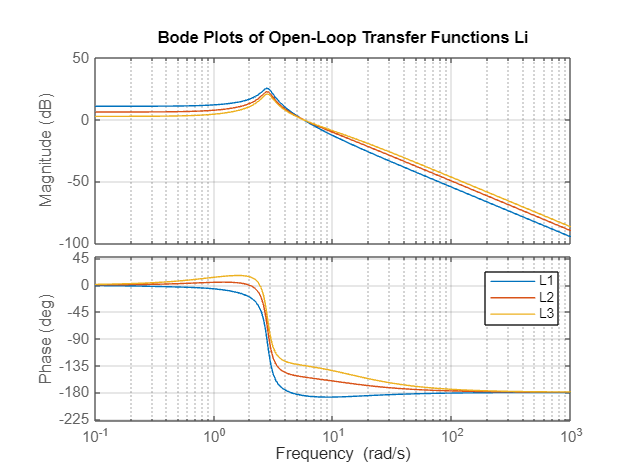

% Assuming G, C1, C2, C3 are defined with the original system parameters 
% from earlier steps. L1, L2, L3 should already be computed as:
% L1 = C1*G; L2 = C2*G; L3 = C3*G;

% Compute sensitivity functions and complementary sensitivity functions for each controller
S1 = feedback(1, L1);   % S1 = 1/(1+L1)
T1 = feedback(L1, 1);   % T1 = L1/(1+L1)

S2 = feedback(1, L2);
T2 = feedback(L2, 1);

S3 = feedback(1, L3);
T3 = feedback(L3, 1);

% Plot Bode diagrams for open-loop transfer functions Li
figure;
bode(L1, L2, L3);
grid on;
title('Bode Plots of Open-Loop Transfer Functions Li');
legend('L1','L2','L3','Location','best');

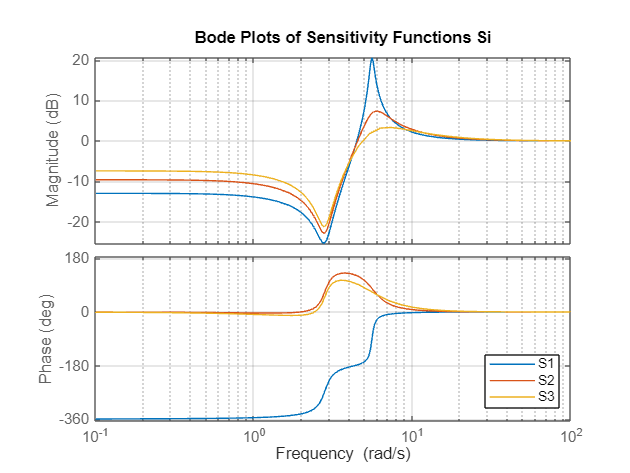


% Plot Bode diagrams for sensitivity functions Si
figure;
bode(S1, S2, S3);
grid on;
title('Bode Plots of Sensitivity Functions Si');
legend('S1','S2','S3','Location','best');

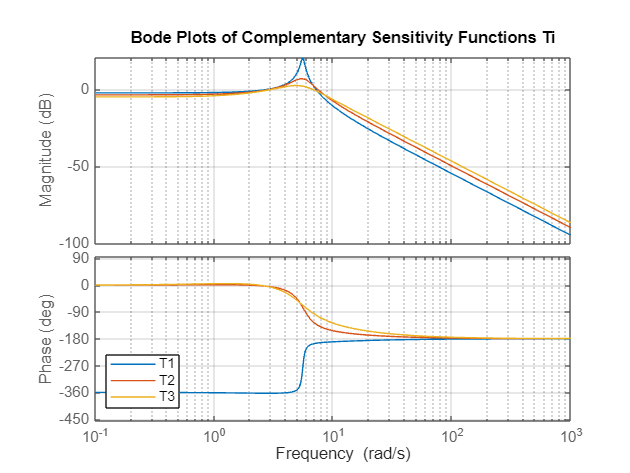


% Plot Bode diagrams for complementary sensitivity functions Ti
figure;
bode(T1, T2, T3);
grid on;
title('Bode Plots of Complementary Sensitivity Functions Ti');
legend('T1','T2','T3','Location','best');